# Stepper Motor 28BJY-48 Spec Values

s = tf('s');

K = 0.0343; %N*m/A
L = 30E-3; % H
R = 50; % ohm

b = 1E-5; %(Assumed Value)
J = 5E-6; %(Assumed Value)

## Second Order System - Voltage to Angular Velocity (Open Loop)

G_2 = K/((L*s + R)*(J*s + b) + (K^2)); % Second Order

% find zeros and poles
zeros_OL_G2 = zero(G_2);
poles_OL_G2 = pole(G_2);
fprintf('Open Loop Zeros:\n');

Open Loop Zeros:


disp(zeros_OL_G2);
fprintf('Open Loop Poles:\n');

Open Loop Poles:


disp(poles_OL_G2);

   1.0e+03 *

   -1.6619
   -0.0067




% DC Gain
DC_gain_OL_G2 = dcgain(G_2);
fprintf('\nDC Gain = %.4f',DC_gain_OL_G2);


DC Gain = 20.4594

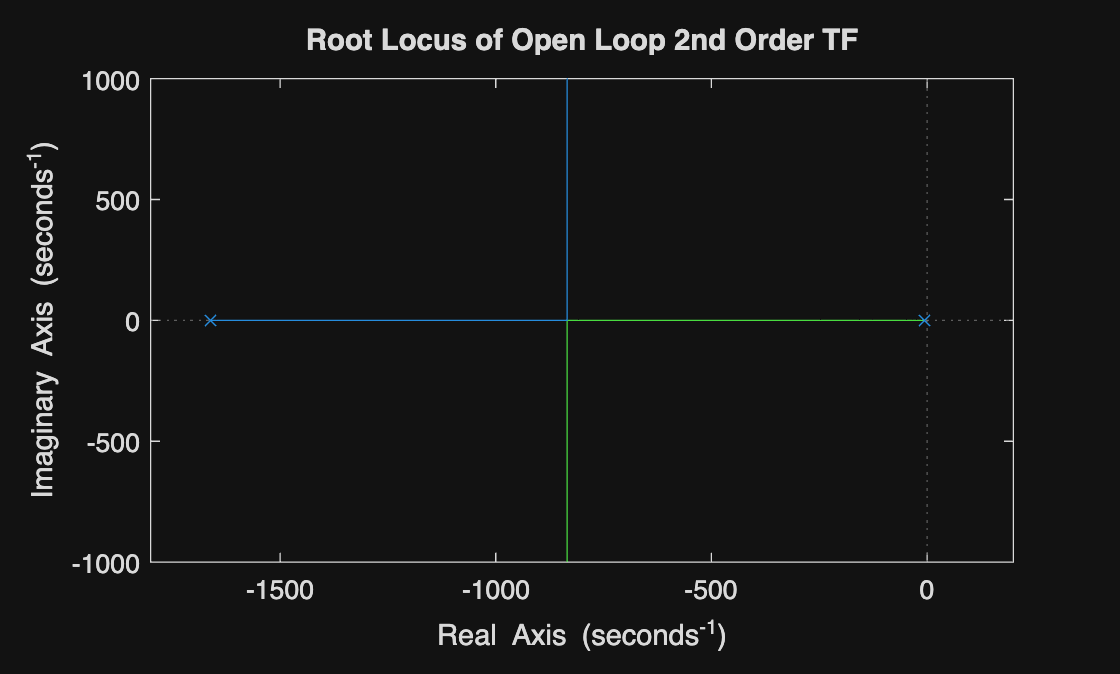


% Root Locus for this system
rlocus(G_2);
title('Root Locus of Open Loop 2nd Order TF');


% Step Response Analysis
fprintf('\n--Step Response Analysis--\n');


--Step Response Analysis--


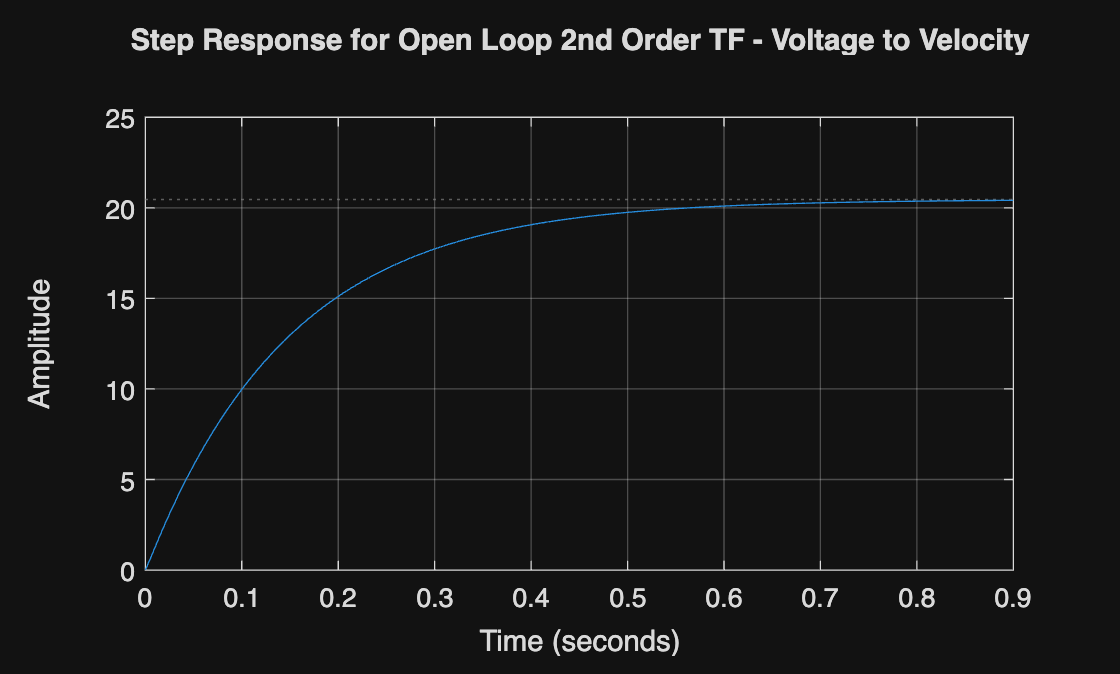

info_OL_G2 = stepinfo(G_2);
figure
step(G_2);
title('Step Response for Open Loop 2nd Order TF - Voltage to Velocity');
grid on;

fprintf('Rise Time Tr       = %.4f \n', info_OL_G2.RiseTime);

Rise Time Tr       = 0.3267 


fprintf('Peak Time Tp       = %.4f \n', info_OL_G2.PeakTime);

Peak Time Tp       = 1.0888 


fprintf('Settling Time Ts       = %.4f \n', info_OL_G2.SettlingTime);

Settling Time Ts       = 0.5823 


fprintf('Overshoot %OS       = %.2f \n', info_OL_G2.Overshoot);

Overshoot 

fprintf('Steady State Value       = %.4f \n', DC_gain_OL_G2);

Steady State Value       = 20.4594 



% Damping & Natural Frequency
if length(poles_OL_G2) >= 2 && abs(imag(poles_OL_G2(1))) > 1e-6
    sigma = abs(real(poles_OL_G2(1)));
    wd = abs(imag(poles_OL_G2(1)));
    wn = sqrt(sigma^2 + wd^2);
    zeta = sigma / wn;  

    fprintf('\n---Dynamic Characteristics--\n');
    fprintf('Natural Frequency = %.4f rad/s\n', wn);
    fprintf('Damping Ratio       = %.4f', zeta);
    if zeta < 0.4
        fprintf(' (Underdamped)\n');
    elseif zeta < 0.7
        fprintf(' (Moderately damped)\n');
    elseif zeta < 1.0
        fprintf(' (Well damped)\n');
    else
        fprintf(' (Overdamped)\n');
    end
    fprintf('Damped Frequency (ωd)  = %.4f rad/s\n', wd);
else
    fprintf('\n--- Dynamic Characteristics ---\n');
    fprintf('System has real poles only (overdamped)\n');
    fprintf('Natural Frequency: N/A\n');
    fprintf('Damping Ratio: ζ > 1\n');
end


--- Dynamic Characteristics ---


System has real poles only (overdamped)


Natural Frequency: N/A


Damping Ratio: ζ > 1


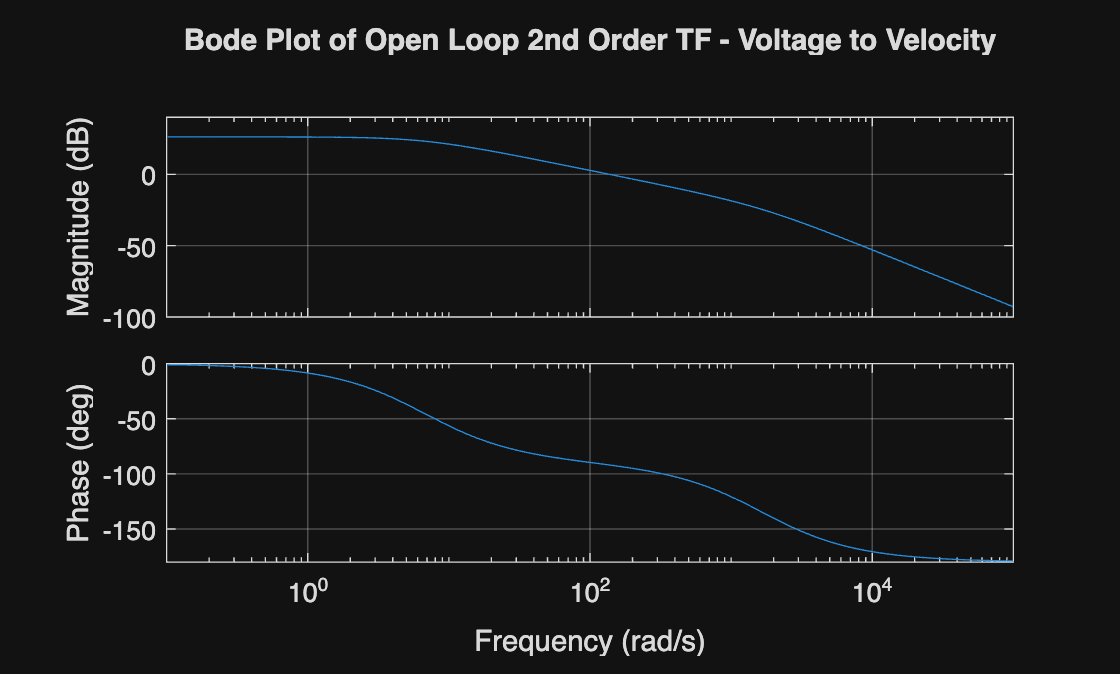


% Bode Plot
figure;
bode(G_2);
title('Bode Plot of Open Loop 2nd Order TF - Voltage to Velocity');
grid on;

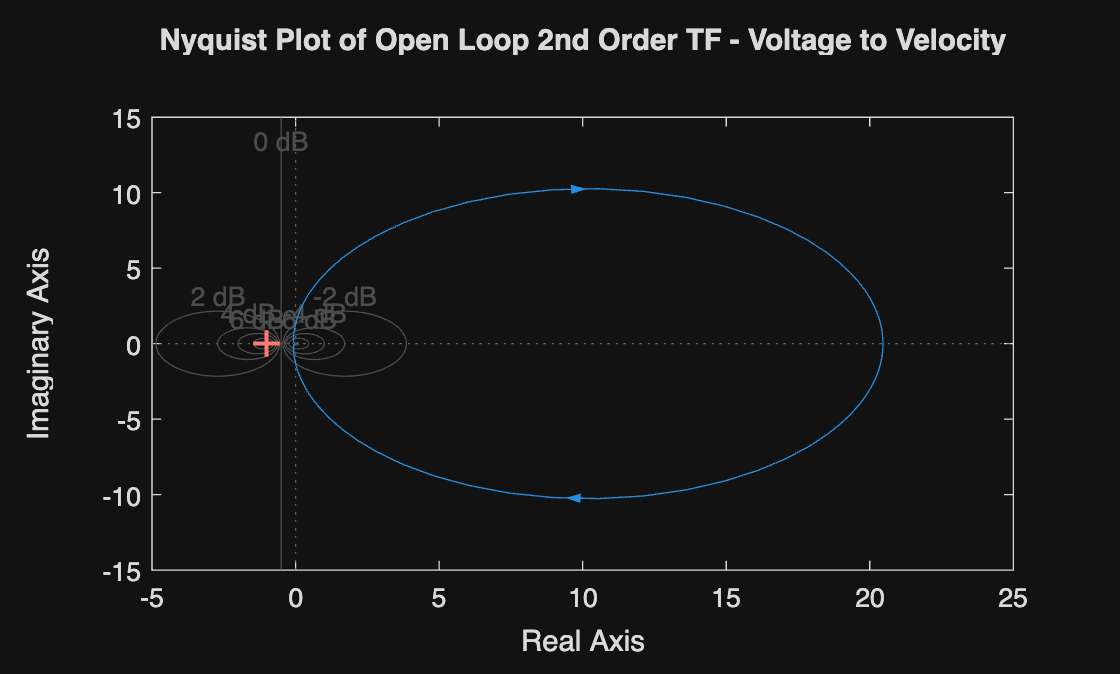

[mag, phase, wout] = bode(G_2);

% Nyquist Plot
figure
nyquist(G_2);
title('Nyquist Plot of Open Loop 2nd Order TF - Voltage to Velocity');
grid on;

## Closed Loop System (Unity Feedback with K = 2) - Step Response

K_gain_G2 = 2;
fprintf('\n\n========================================\n');

fprintf('Close Loop Analysis\n');

Close Loop Analysis


fprintf('Feedback Gain K = %.1f\n', K_gain_G2);

Feedback Gain K = 2.0


fprintf('========================================\n\n');


T_G2 = feedback(K_gain_G2*G_2, 1);
fprintf('T(s) = (K*G)/(1 + K*G)\n\n');

T(s) = (K*G)/(1 + K*G)




% find zeros and poles
zeros_CL_G2 = zero(T_G2);
poles_CL_G2 = pole(T_G2);
fprintf('Closed Loop Zeros:\n');

Closed Loop Zeros:


disp(zeros_CL_G2);
fprintf('Closed Loop Poles:\n');

Closed Loop Poles:


disp(poles_CL_G2);

   1.0e+03 *

   -1.3114
   -0.3573




% DC Gain
DC_gain_CL_G2 = dcgain(T_G2);
fprintf('\nDC Gain = %.4f',DC_gain_CL_G2);


DC Gain = 0.9761


% Root Locus for this system
pzmap(T_G2);

Error using DynamicSystem/pzmap (line 68)
Dot indexing is not supported for variables of this type.

title('Root Locus of Closed Loop 2nd Order TF');

% Step Response Analysis
fprintf('\n--Step Response Analysis--\n');
info_CL_G2 = stepinfo(T_G2);
figure
step(T_G2);
title('Step Response for Closed Loop 2nd Order TF - Voltage to Velocity');
grid on;
fprintf('Rise Time Tr       = %.4f \n', info_CL_G2.RiseTime);
fprintf('Peak Time Tp       = %.4f \n', info_CL_G2.PeakTime);
fprintf('Settling Time Ts       = %.4f \n', info_CL_G2.SettlingTime);
fprintf('Overshoot %OS       = %.2f \n', info_CL_G2.Overshoot);
fprintf('Steady State Value       = %.4f \n', DC_gain_CL_G2);

% Damping & Natural Frequency
if length(poles_CL_G2) >= 2 && abs(imag(poles_CL_G2(1))) > 1e-6
    sigma = abs(real(poles_CL_G2(1)));
    wd = abs(imag(poles_CL_G2(1)));
    wn = sqrt(sigma^2 + wd^2);
    zeta = sigma / wn;  

    fprintf('\n---Dynamic Characteristics--\n');
    fprintf('Natural Frequency = %.4f rad/s\n', wn);
    fprintf('Damping Ratio       = %.4f', zeta);
    if zeta < 0.4
        fprintf(' (Underdamped)\n');
    elseif zeta < 0.7
        fprintf(' (Moderately damped)\n');
    elseif zeta < 1.0
        fprintf(' (Well damped)\n');
    else
        fprintf(' (Overdamped)\n');
    end
    fprintf('Damped Frequency (ωd)  = %.4f rad/s\n', wd);
else
    fprintf('\n--- Dynamic Characteristics ---\n');
    fprintf('System has real poles only (overdamped)\n');
    fprintf('Natural Frequency: N/A\n');
    fprintf('Damping Ratio: ζ > 1\n');
end

% Bode Plot
figure
bode(T_G2);
title('Bode Plot of Closed Loop 2nd Order TF - Voltage to Velocity');
grid on;
[mag, phase, wout] = bode(T_G2);

% Nyquist Plot
figure
nyquist(T_G2);
title('Nyquist Plot of Closed Loop 2nd Order TF - Voltage to Velocity');
grid on;

## Third Order System - Voltage to Position (Open Loop)

G_3 = K/(s*((L*s + R)*(J*s + b) + K^2)); % Added an integrator as theta = omega/s

% find zeros and poles
zeros_OL_G3 = zero(G_3);
poles_OL_G3 = pole(G_3);
fprintf('Open Loop Zeros:\n');
disp(zeros_OL_G3);
fprintf('Open Loop Poles:\n');
disp(poles_OL_G3);

% DC Gain
DC_gain_OL_G3 = dcgain(G_3);
fprintf('\nDC Gain = %.4f',DC_gain_OL_G3);

% Root Locus for this system
rlocus(G_3);
title('Root Locus of Open Loop 3rd Order TF');

% Step Response Analysis
fprintf('\n--Step Response Analysis--\n');
info_OL_G3 = stepinfo(G_3);
figure
step(G_3);
title('Step Response for Open Loop 3rd Order TF - Voltage to Position');
grid on;
fprintf('Rise Time Tr       = %.4f \n', info_OL_G3.RiseTime);
fprintf('Peak Time Tp       = %.4f \n', info_OL_G3.PeakTime);
fprintf('Settling Time Ts       = %.4f \n', info_OL_G3.SettlingTime);
fprintf('Overshoot %OS       = %.2f \n', info_OL_G3.Overshoot);
fprintf('Steady State Value       = %.4f \n', DC_gain_OL_G3);

% Damping & Natural Frequency
if length(poles_OL_G3) >= 2 && abs(imag(poles_OL_G3(1))) > 1e-6
    sigma = abs(real(poles_OL_G3(1)));
    wd = abs(imag(poles_OL_G3(1)));
    wn = sqrt(sigma^2 + wd^2);
    zeta = sigma / wn;  
    
    fprintf('Natural Frequency ωn = %.4f rad/s\n', wn);
    fprintf('Damping Ratio ζ = %.4f (Underdamped!)\n', zeta);
    fprintf('Damped Frequency ωd = %.4f rad/s\n', wd);

    fprintf('\n---Dynamic Characteristics--\n');
    fprintf('Natural Frequency = %.4f rad/s\n', wn);
    fprintf('Damping Ratio       = %.4f', zeta);
    if zeta < 0.4
        fprintf(' (Underdamped)\n');
    elseif zeta < 0.7
        fprintf(' (Moderately damped)\n');
    elseif zeta < 1.0
        fprintf(' (Well damped)\n');
    else
        fprintf(' (Overdamped)\n');
    end
    fprintf('Damped Frequency (ωd)  = %.4f rad/s\n', wd);
else
    fprintf('\n--- Dynamic Characteristics ---\n');
    fprintf('System has real poles only (overdamped)\n');
    fprintf('Natural Frequency: N/A\n');
    fprintf('Damping Ratio: ζ > 1\n');
end

% Bode Plot
figure
bode(G_3);
title('Bode Plot of Open Loop 3rd Order TF - Voltage to Position');
grid on;
[mag, phase, wout] = bode(G_3);

% Nyquist Plot
figure
nyquist(G_3);
title('Nyquist Plot of Open Loop 3rd Order TF - Voltage to Position');
grid on;

## Closed Loop System (Unity Feedback with K = 2) - Step Response

K_gain_G3 = 1;
fprintf('\n\n========================================\n');
fprintf('Close Loop Analysis\n');
fprintf('Feedback Gain K = %.1f\n', K_gain_G3);
fprintf('========================================\n\n');

T_G3 = feedback(K_gain_G3*G_3, 1);
fprintf('T(s) = (K*G)/(1 + K*G)\n\n');

% find zeros and poles
zeros_CL_G3 = zero(T_G3);
poles_CL_G3 = pole(T_G3);
fprintf('Closed Loop Zeros:\n');
disp(zeros_CL_G3);
fprintf('Closed Loop Poles:\n');
disp(poles_CL_G3);

% DC Gain
DC_gain_CL_G3 = dcgain(T_G3);
fprintf('\nDC Gain = %.4f',DC_gain_CL_G3);

% Root Locus for this system
pzmap(T_G3);
title('Root Locus of Closed Loop 3rd Order TF');

% Step Response Analysis
fprintf('\n--Step Response Analysis--\n');
info_CL_G3 = stepinfo(T_G3);
figure
step(T_G3);
title('Step Response for Closed Loop 3rd Order TF - Voltage to Position');
grid on;
fprintf('Rise Time Tr       = %.4f \n', info_CL_G3.RiseTime);
fprintf('Peak Time Tp       = %.4f \n', info_CL_G3.PeakTime);
fprintf('Settling Time Ts       = %.4f \n', info_CL_G3.SettlingTime);
fprintf('Overshoot %OS       = %.2f \n', info_CL_G3.Overshoot);
fprintf('Steady State Value       = %.4f \n', DC_gain_CL_G3);

% Damping & Natural Frequency
if length(poles_CL_G3) >= 2 && abs(imag(poles_CL_G3(1))) > 1e-6
    sigma = abs(real(poles_CL_G3(1)));
    wd = abs(imag(poles_CL_G3(1)));
    wn = sqrt(sigma^2 + wd^2);
    zeta = sigma / wn;
    disp(zeta);

    fprintf('\n---Dynamic Characteristics--\n');
    fprintf('Natural Frequency = %.4f rad/s\n', wn);
    fprintf('Damping Ratio       = %.4f', zeta);
    if zeta < 0.4
        fprintf(' (Underdamped)\n');
    elseif zeta < 0.7
        fprintf(' (Moderately damped)\n');
    elseif zeta < 1.0
        fprintf(' (Well damped)\n');
    else
        fprintf(' (Overdamped)\n');
    end
    fprintf('Damped Frequency (ωd)  = %.4f rad/s\n', wd);
else
    fprintf('\n--- Dynamic Characteristics ---\n');
    fprintf('System has real poles only (overdamped)\n');
    fprintf('Natural Frequency: N/A\n');
    fprintf('Damping Ratio: ζ > 1\n');
end

% Bode Plot
figure
bode(T_G3);
title('Bode Plot of Closed Loop 3rd Order TF - Voltage to Position');
grid on;
[mag, phase, wout] = bode(T_G3);

% Nyquist Plot
figure
nyquist(T_G3);
title('Nyquist Plot of Closed Loop 3rd Order TF - Voltage to Position');
grid on;
